**Aerodynamics via Unsteady and Quasi-Steady Methods                                                                                                         Ari Barnett - Mathematical Modeling Project 5**

Classical aeroelasticity analysis examines aerodynamic forces, structure elasticity, and inertial forces. This type of analysis is important to the design of aircraft to mitigate instability and avoid disaster. Likewise this leads the aircraft optimization and robust designs. 

For this project we were tasked with programming and solving for Lift Coefficients and Moment Coefficients over time via Unsteady Aerodynamics. Specifically, the provided code simulates the unsteady aerodynamics of an oscillating airfoil using the discrete vortex method and calculates the lift and moment coefficients at different time steps (figure 1).

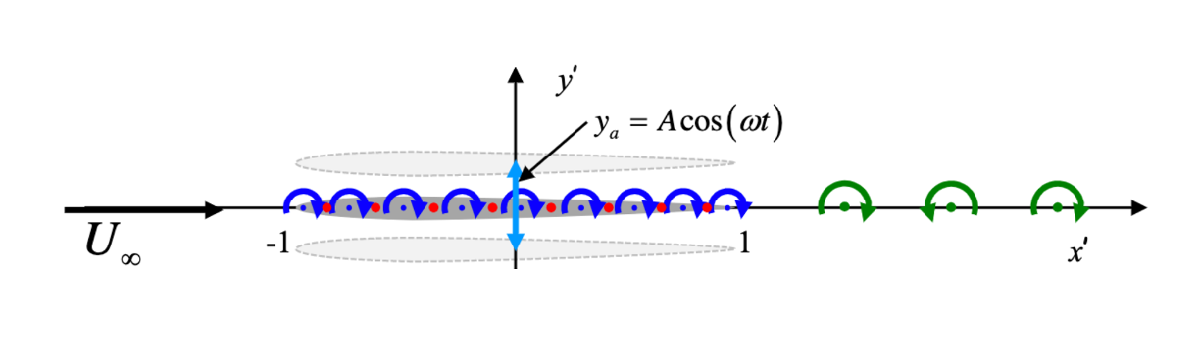

Figure 1 : Visual Example of Oscilating Airfoil to be simulated.

To approach this problem, we must solve the system of equations defined by:

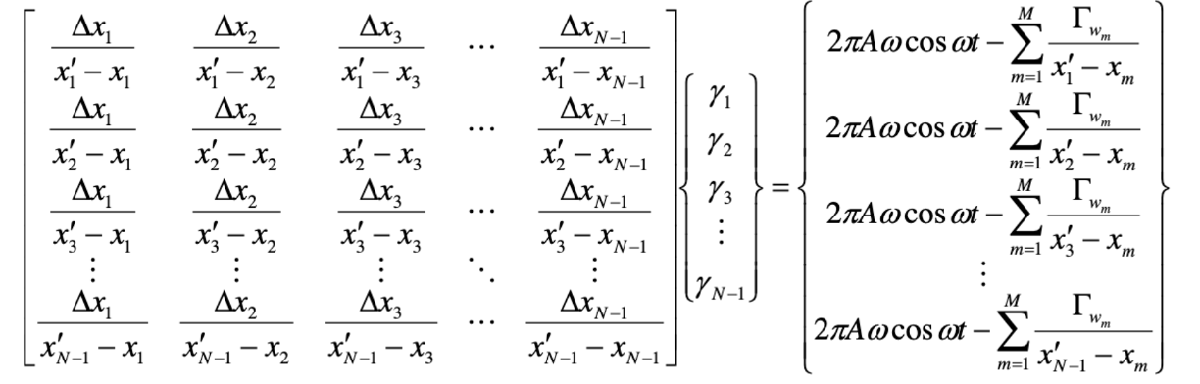

Where the variables are defined as:

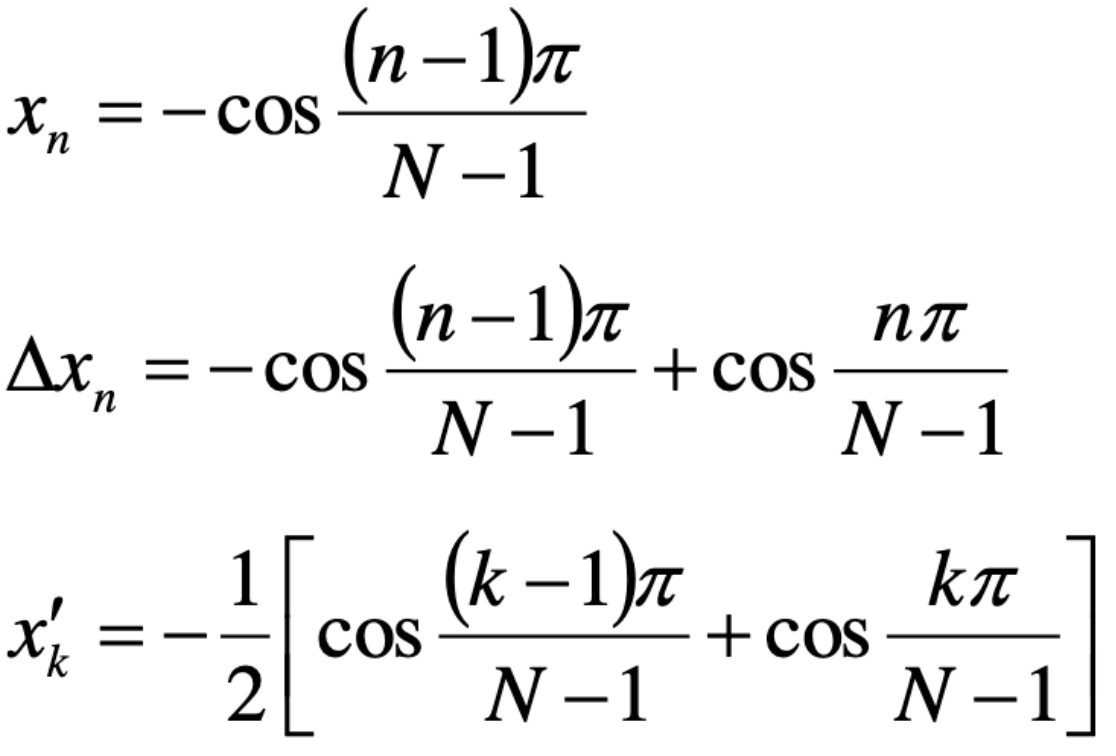

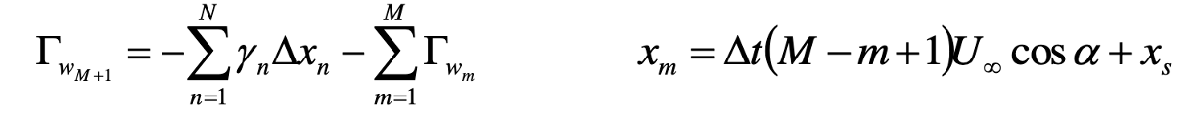

From provided examples - under the A and Omega condtion (0.01, 2) we should obtain a result similar to the following:

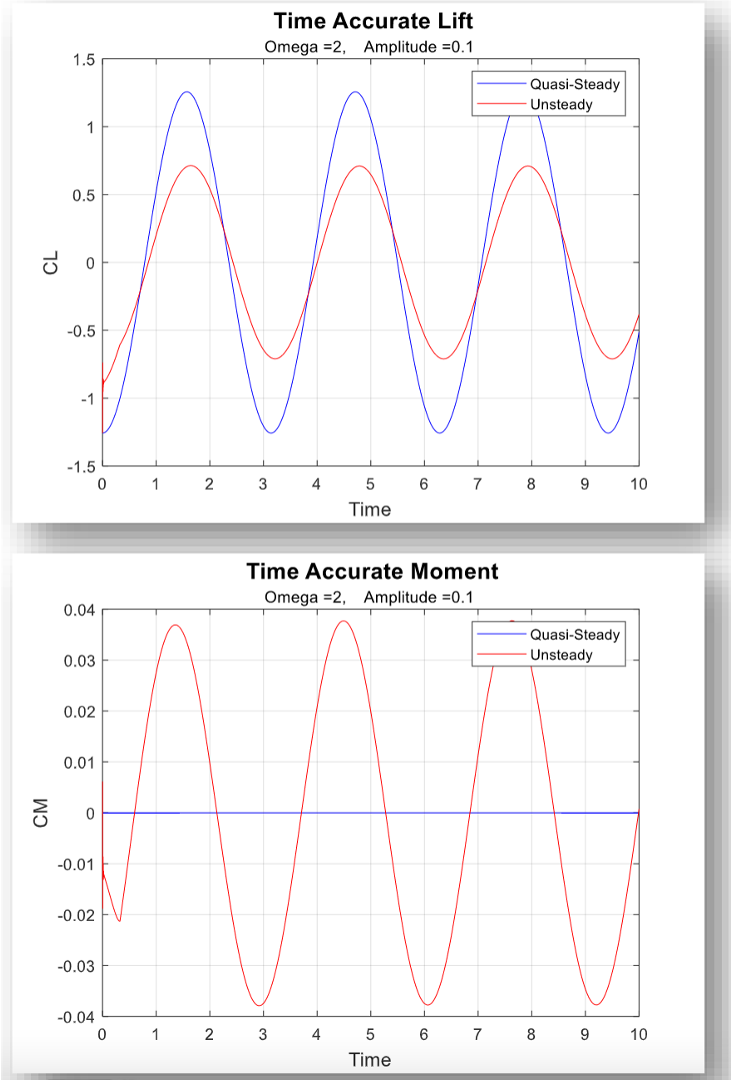

To study the behavior we implement both a Quasi-Steady and Unsteady approach. With unsteady aerodynamics - the flow parameters or the object's geometry change rapidly with time. This can result from many reasons (oscillation of the wing structure or turbulence for example). Mathematically this approach is also far more complex as it requires fluid dynamics simulation. Quasi-Steady allows for a drastic simplification of dynamics and assumes instant changes.

Here we present the code utilized and visualized resutls:

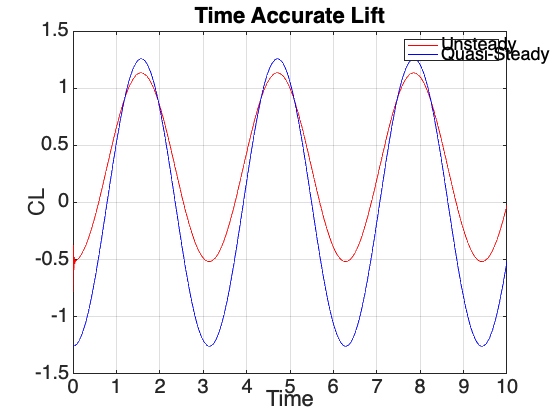

%Project 5 Unsteady Aerodynamics 
%Barnett, Ari 


%Define Parameters for Amplitude, Omega, Time Span, and N
N = 100;
tspan = 0:0.01:10;
A = 0.1;
omega = 2;


%==========Define LHS and RHS matrices=====================

%LHS
[xn_grid, x_prime_k_grid] = meshgrid(xn(1:(N-1),N), x_prime_k(1:(N-1),N));
delta_xn_grid = repmat(delta_xn(1:(N-1),N), N-1, 1);
LHS = delta_xn_grid ./ (x_prime_k_grid - xn_grid);

%Extract Delta Xn values
dx = delta_xn_grid(1,:)';

%Extract X_prime_k Values
x_prime_k_values = x_prime_k_grid(:,1);

%==========RHS========================

%Set inital values for vectors/matrices
GammaVector(1) = 0;
vortex_accumulation(1) = 0;

SumGamma(1) = 0;
SumGammaDeltaXn(1) = 0;


for m = 1:length(tspan)
    for M = 1:m
        xm_params = [0.01, m , M, 1, 0, 2.5];
        xm_collect(M) = xm(xm_params);
    end 


    vortex_accumulation = vortex_accumulation(:) + (GammaVector(m)./(x_prime_k_values(:) - xm_collect(m)));
    RHS_value= RHS(A,omega,vortex_accumulation,tspan(m));
    
    %Solve for little gamma_n
    gamma_n = LHS\RHS_value; 

    %Sovle and Update Captial Gamma Values
    SumGammaDeltaXn = sum(gamma_n.*dx);
    SumGamma = SumGamma + GammaVector(m); 

    GammaVector(m+1) = - SumGammaDeltaXn - SumGamma;

    %Collect Lift and Moment Coefficients
    LC_Vector(m) = LiftCoeffiecient(SumGammaDeltaXn);
    LM_Vector(m) = MomentCoeffiecient(xn_grid(1,:),gamma_n, delta_xn_grid(1,:));

end

figure()
plot(tspan,-LC_Vector,'r')
title("Time Accurate Lift")
xlabel("Time")
ylabel("CL")

hold on
plot(tspan,-2*pi*(A*omega*cos(omega*tspan)),'b')
grid on
legend("Unsteady", "Quasi-Steady")

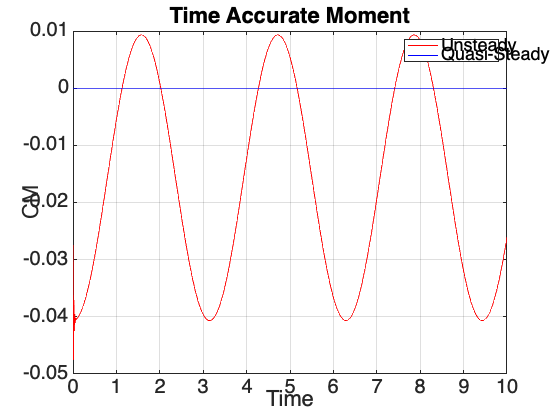


figure()
plot(tspan,-LM_Vector,'r')
title("Time Accurate Moment")
xlabel("Time")
ylabel("CM")

hold on
plot(tspan,-((-0.5+0.5)*pi*A*omega*cos(omega*tspan)),'b')
grid on
legend("Unsteady", "Quasi-Steady")



%=========Collection of Functions to Use============ 

function xn_value = xn(n,N)
xn_value = -cos( ...
    (n-1)*pi / (N - 1));
end

%====DELTA XN CALCULATION======
function delta_xn_value = delta_xn(n,N)
delta_xn_value = -cos( ...
    ((n-1)*pi) / (N - 1)) + cos(n*pi/ (N-1));
end

%====X PRIME CALCULATION======
function x_prime_k_value = x_prime_k(K,N)
x_prime_k_value = -(1/2)*(cos( ...
    (K-1)*pi / (N - 1)) + cos((K*pi) / (N-1)));
end

%====RIGHT HAND SIDE CALCULATION======
function rhs_value = RHS(A,omega,Gamma, t)
    rhs_value = (2*pi*A*omega*cos(omega*t)) - Gamma;
end

%====Xm CALCULATION======
function xm_values = xm(parameters)
    time_delta = parameters(1);
    m = parameters(2);
    M = parameters(3);
    U_infinity = parameters(4);
    alpha = parameters(5);
    xs = parameters(6);

    xm_values = (time_delta*(M-m+1)*U_infinity*cos(alpha)) + xs;
end

%====LIFT CALCULATION======
function LC = LiftCoeffiecient(SumGammaDeltaXN)
    LC = SumGammaDeltaXN;
end

%====MOMENT CALCULATION======
function LM = MomentCoeffiecient(xn,gamma,deltaXn)
    LM = (1/2)*sum((-0.5 - xn)*(gamma.*(deltaXn')));
end


From these results we see a noticable left shift in comparison to the original results. Likewise, when originally run the results seem to be inverted therefore the results are multipled by -1 to give a better visual comparison. 

**SIDE NOTES:**

What exactly is wrong? (Question for myself and others cause I aint got a clue). Main takeaway from this project: I am not working at Lockheed Martin (yet...)